% DATA=ImportTmVO4Cp('TmVO4_Mosaic_2017-07-28.dat');
DATA=ImportTmVO4Cp('TmVO4_RF-E_2017-07-14.dat');

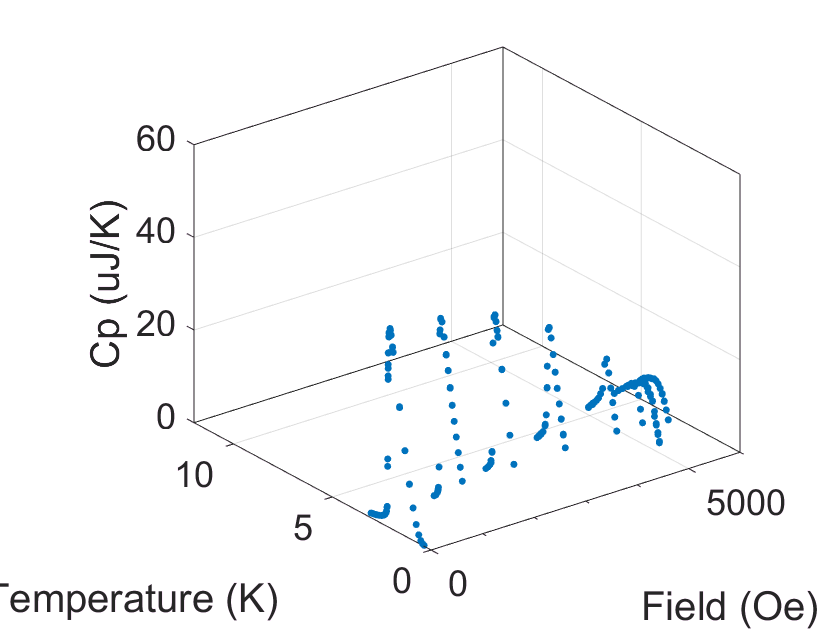

H=[DATA.FieldOersted];
T=[DATA.SampleTempKelvin];
Cp=[DATA.SampHCJmoleK];

whichPoints = isfinite(H) & isfinite(T) & isfinite(Cp);
H=H(whichPoints);
T=T(whichPoints);
Cp=Cp(whichPoints);

hmax=32000;
tmin = 1.8;
tmax = 12;
scatter3(H,T,Cp,'.')
% xlim([0 hmax])
ylim([0 tmax])
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('Cp (uJ/K)')

tstep=0.1; 
hstep=1000;
[Hg,Tg] = meshgrid(0:hstep:hmax,tmin:tstep:tmax);% for griddata
Hgl=0:hstep:hmax;% for gridfit
Tgl=tmin:tstep:tmax;% for gridfit
figure
Cpg = gridfit(H,T,Cp,Hgl,Tgl);

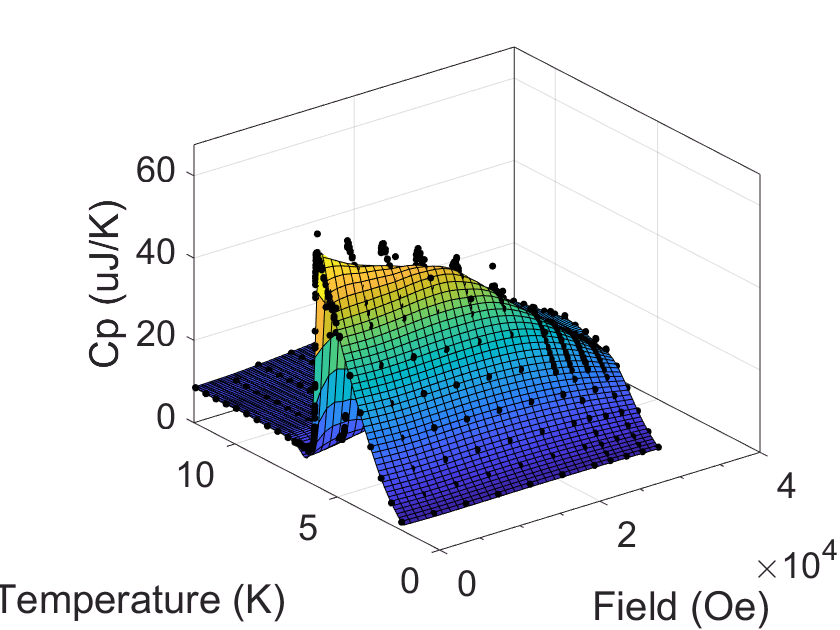

%Cpg = griddata(H,T,Cp,Hg,Tg);
surf(Hg,Tg,Cpg)
hold on
scatter3(H,T,Cp,100,'.','.k')
ylim([0 tmax])
zlim([0 1.1*max(Cp)])
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('Cp (uJ/K)')

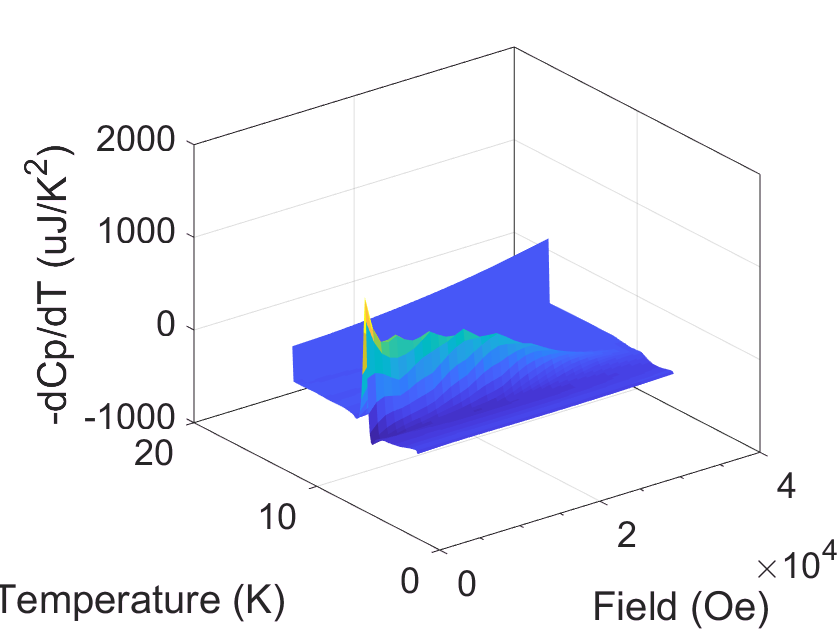

steps = -50:50;
x= tstep*steps;
s=0.05;
d1Gaussian = -exp(-x.^2/(2*s^2)).*x./sqrt(s^6*2*pi);% first derivative of a Gaussian
d2Gaussian = exp(-x.^2/(2*s^2)).*(x.^2 - s^2)/sqrt(s^10*2*pi);% second derivative of a Gaussian

figure
d1Cpg = conv2(Cpg,d1Gaussian','same');
d2Cpg = conv2(Cpg,d2Gaussian','same');
surf(Hg,Tg,-d1Cpg,'EdgeColor','none')
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('-dCp/dT (uJ/K^2)')

clear separatedCpData

fields = 0:4000:32000;

for i = 1:length(fields)
    wp = abs(H-fields(i))<50;
    separatedCpData(i).H = H(wp);
    separatedCpData(i).T = T(wp);
    separatedCpData(i).Cp = Cp(wp);
    
    [separatedCpData(i).T,wo] = sort(separatedCpData(i).T);
    separatedCpData(i).H = separatedCpData(i).H(wo);
    separatedCpData(i).Cp = separatedCpData(i).Cp(wo);
end

## Plot Cp(T)

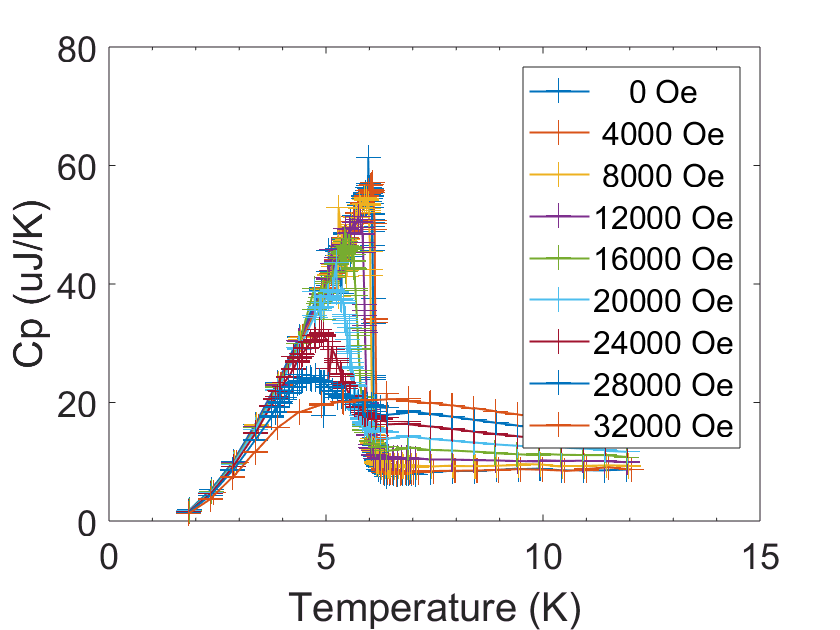

for i=1:length(fields)
    plot(separatedCpData(i).T,separatedCpData(i).Cp,'-+')
    hold on
end
xlabel('Temperature (K)')
ylabel('Cp (uJ/K)')
legendCell = cellstr(num2str(fields', '%-d Oe'));
legend(legendCell)
hold off

## Plot Cp/T(T)

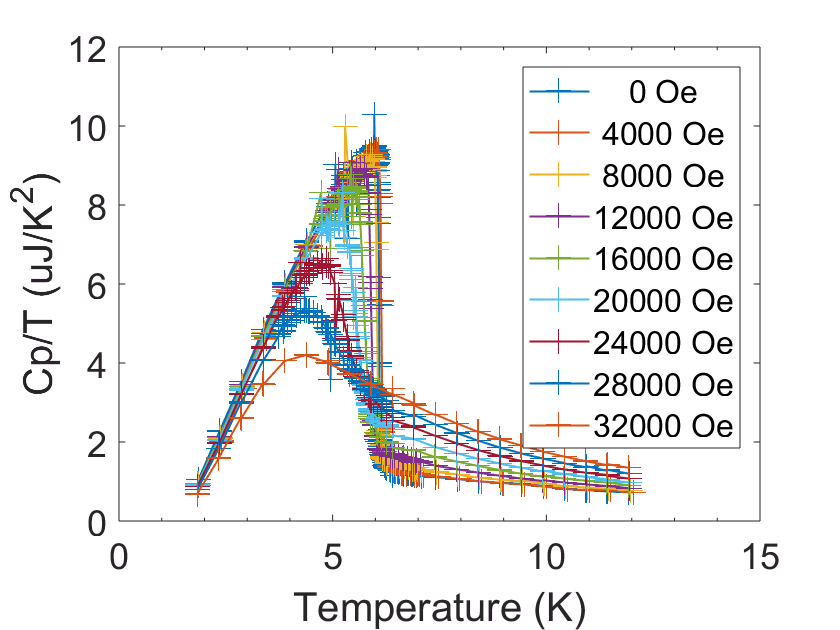

for i=1:length(fields)
    plot(separatedCpData(i).T,separatedCpData(i).Cp./separatedCpData(i).T,'-+')
    hold on
end
xlabel('Temperature (K)')
ylabel('Cp/T (uJ/K^2)')
legendCell = cellstr(num2str(fields', '%-d Oe'));
legend(legendCell)
hold off

whichT = 1.8:0.1:6.1;
clear cstTCpdata
for i=length(whichT):-1:1
    if length(T(abs(T-whichT(i))<0.005)) < 4
        whichT(i) = [];
    end
end

for i=1:length(whichT)
    cstTfilter = abs(T-whichT(i))<0.01;
    cstTCpdata(i).H = H(cstTfilter);
    cstTCpdata(i).T = T(cstTfilter);
    cstTCpdata(i).Cp = Cp(cstTfilter);
    
    [cstTCpdata(i).H,wo] = sort(cstTCpdata(i).H);
    cstTCpdata(i).H = cstTCpdata(i).H(wo);
    cstTCpdata(i).Cp = cstTCpdata(i).Cp(wo);
end

For each value of temperature rounded to 0.1K (whichT), identify the closest tempertaure value measured and store this value and the corresponding Cp value

## Plot Cp(H) at constant T

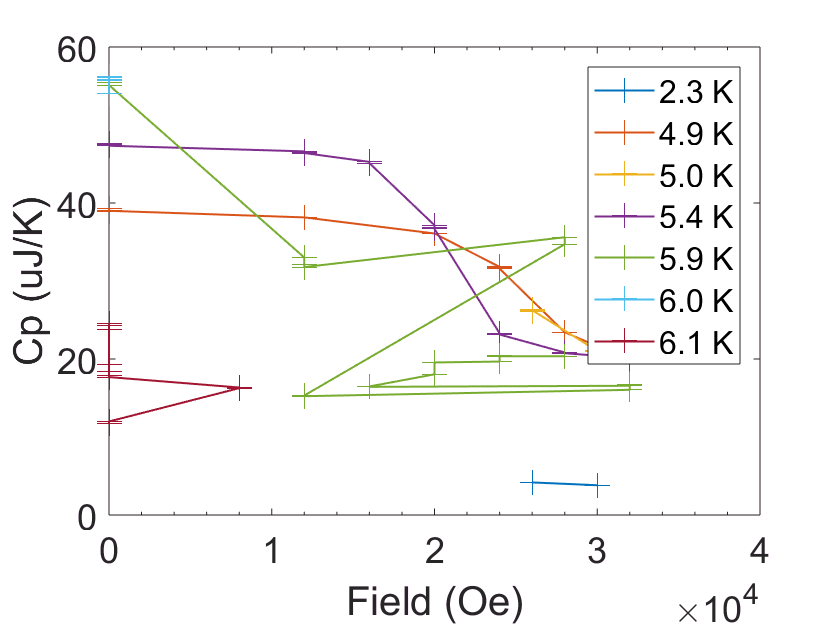

index = 1:length(whichT);
for i=index
    plot(cstTCpdata(i).H,cstTCpdata(i).Cp,'-+')
    hold on
end
xlabel('Field (Oe)')
ylabel('Cp (uJ/K)')
legendCell = cellstr(num2str(whichT(index)', '%1.1f K'));
legend(legendCell)
hold off

## Plot Cp/T(H) at constant T

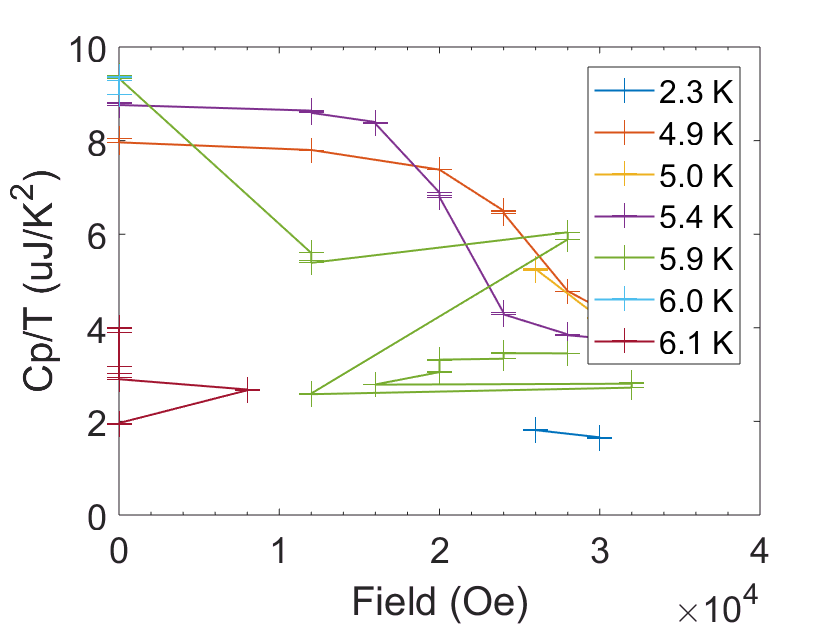

index = 1:length(whichT);
for i=index
    plot(cstTCpdata(i).H,cstTCpdata(i).Cp./cstTCpdata(i).T,'-+')
    hold on
end
xlabel('Field (Oe)')
ylabel('Cp/T (uJ/K^2)')
legendCell = cellstr(num2str(whichT(index)', '%1.1f K'));
legend(legendCell)
hold off

Next steps: 

- save file in TmAsO4 folder

- plot Cp/T = f(T)

- Calculate Cp = f(H) at fixed temperature

## Below this point: code not adapted yet

x=separatedCpData(4).T;
y=separatedCpData(4).Cp;

for i=1:length(fields)
    separatedCpData(i).f=fitSpline(separatedCpData(i).T,-separatedCpData(i).Cp);
%Is fitSpline a Matlab function? Cannot find it in the help.
%    separatedCpData(i).d2=differentiate(separatedCpData(i).f,separatedCpData(i).T);
    plot(separatedCpData(i).f,'deriv1')
    hold on
end
legend(legendCell)
xlabel('Temperature (K)')
ylabel('-dCp/dT (uJ/K^2)')
hold off

figure
% n = length(fields);
% C=[]
% for i=0:n-1
%     C=[C; 1-i/n i/n 0];
% end
% set(0,'defaultaxescolororder',C) %red to green
for i=1:length(fields)
    separatedCpData(i).f=fitSpline(separatedCpData(i).T,separatedCpData(i).Cp);
    separatedCpData(i).d2=differentiate(separatedCpData(i).f,separatedCpData(i).T);
    scatter3(separatedCpData(i).H,separatedCpData(i).T,-separatedCpData(i).d2,'filled')
    hold on
end
xlim([0 hmax])
ylim([0 3])
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('-dCp/dT (uJ/K)')
hold off

T2=[];
H2=[];
d2Cp2=[];
for i=1:length(fields)
    T2= [T2; separatedCpData(i).T];
    H2=[ H2; separatedCpData(i).H];
    d2Cp2=[d2Cp2; separatedCpData(i).d2];
end

tstep=0.025;
% hmax=8000;
% hstep=500;
% [Hg,Tg] = meshgrid(0:hstep:hmax,tmin:tstep:3);%for griddata
Hgl=0:hstep:hmax;%for gridfit
Tgl=tmin:tstep:3;%for gridfit
figure
d2Cpgf = gridfit(H2,T2,d2Cp2,Hgl,Tgl);
d2Cpg = griddata(H2,T2,d2Cp2,Hg,Tg);
surf(Hg,Tg,-d1Cpg,'EdgeColor','none')
xlabel('Field (Oe)')
ylabel('Temperature (K)')
zlabel('-dCp/dT (uJ/K^3)')
hold on
%scatter3(H2,T2,-d2Cp2,'.k')
xlim([0 hmax])
ylim([0 3])